## Simulate initial LIGO data with CBC signal

Specify the data length and sampling frequency.

%Data length
dataLen = 20;%sec
%Sampling frequency
samplFreq = 2048; %Hz
nSamples = floor(dataLen*samplFreq);
timeVec = (0:(nSamples-1))/samplFreq;

Generate a Newtonian chirp using the parameters below.

addpath ../SIGNALS/
%Signal-to-noise ratio
snr = 10;
%time of arrival
timeArrival = 7.2;%sec
%Chirp time
chirpTime = 5; %sec
%initial phase
phi0 = pi/1.7;
%The signal has unit norm under the assumption of white Gaussian noise
[sigVec, sigLen] = newtchirp(nSamples, timeArrival, chirpTime, phi0, samplFreq);

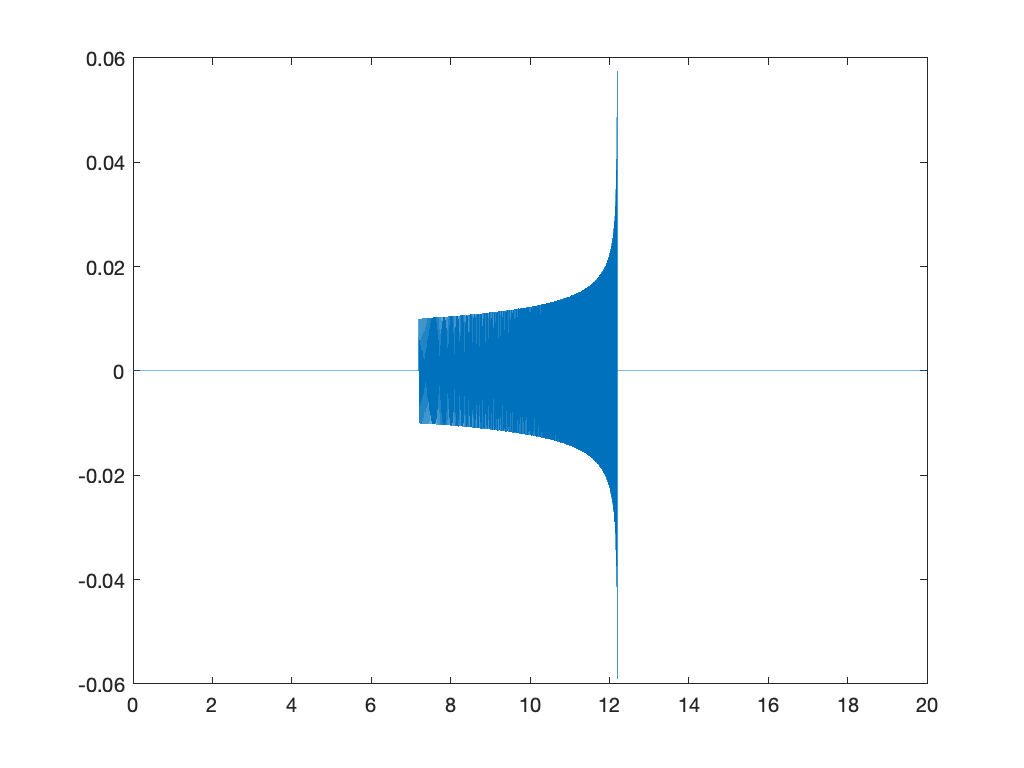

figure;
plot(timeVec,sigVec);

Generate noise with initial LIGO PSD. The target PSD is the design sensitivity given in the file [iLIGOSensitivity.txt](matlab:open('../NOISE/iLIGOSensitivity.txt')).

addpath ../NOISE/
%Filter order for generating colored noise 
fltrOrdrGWNoise = 300;
%Low and high frequency cutoffs for the target PSD
fLo = 40; %Hz
fHi = 700; %Hz
[noiseVec,psdVec] = gengwnoise(nSamples,300,samplFreq,40,800,'iLigo');


Plot the estimated PSD of the simulated noise and compare with the target PSD.

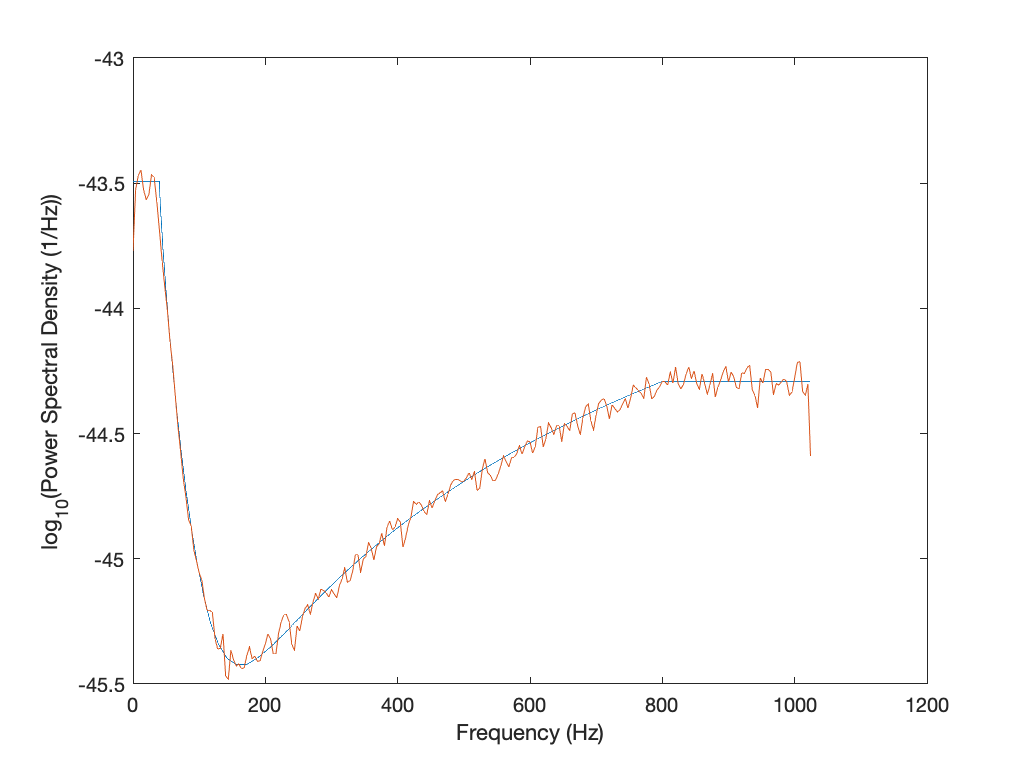

figure;
kNyq = floor(nSamples/2)+1;
posFreq = (0:(kNyq-1))*samplFreq/nSamples;
plot(posFreq,log10(psdVec));
hold on;
[pxx,f] = pwelch(noiseVec,512,[],[],samplFreq);
%Convert from one-sided PSD returned by pwelch to 2-sided
plot(f,log10(pxx/2));
 xlabel('Frequency (Hz)');
 ylabel('log_{10}(Power Spectral Density (1/Hz))');

Normalize the signal to have the specified SNR under the target PSD.